# Problem 1

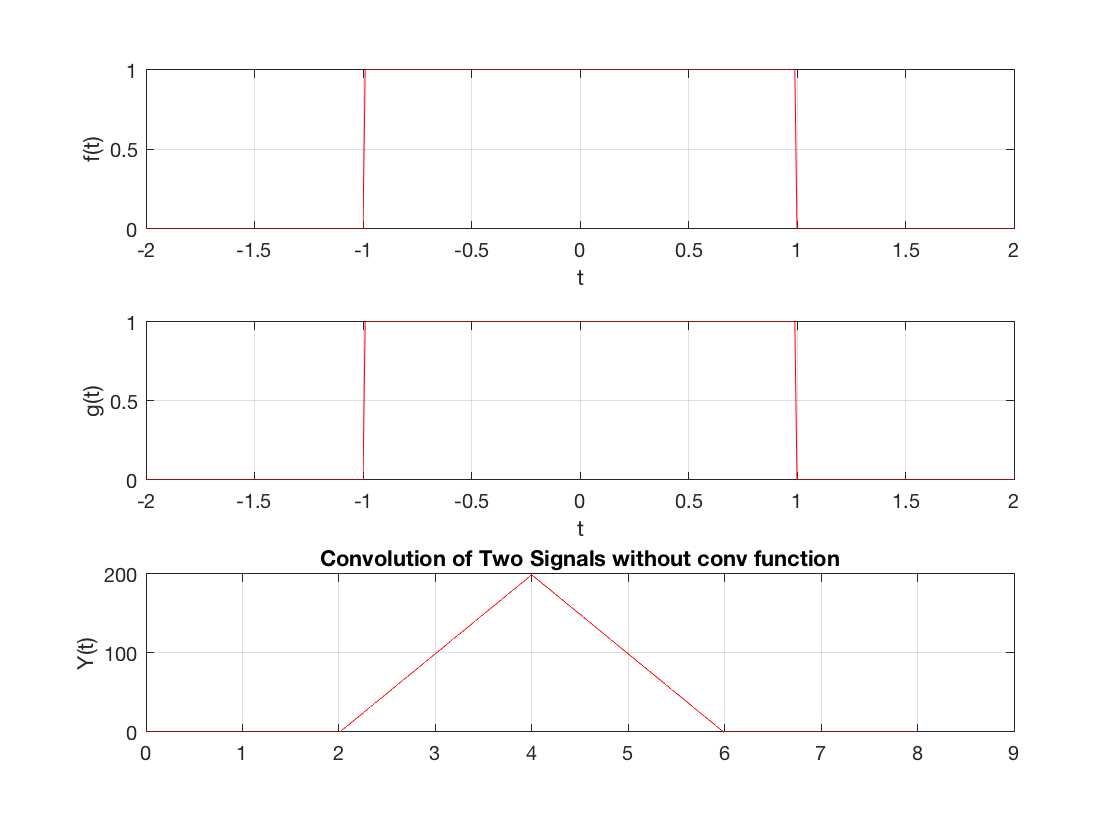

% (b)

close all
clearvars

A = 1;
a = 1;
t = -a*2:0.01:a*2;

f= A*(a>abs(t)); 
g= A*(a>abs(t)); 

% convolution
m=length(f);
n=length(g);
X=[f,zeros(1,n)];
H=[g,zeros(1,m)];
for i=1:n+m-1
    Y(i)=0;
    for j=1:m
        if(i-j+1>0)
            Y(i)=Y(i)+X(j)*H(i-j+1);
        else
        end
    end
end

% plot results
figure;
subplot(3,1,1); plot(t,f, '-r'); xlabel('t');
ylabel('f(t)'); grid on;

subplot(3,1,2); plot(t,g, '-r');
xlabel('t'); ylabel('g(t)'); grid on;

axis=(0:length(Y)-1)*(t(2)-t(1));
subplot(3,1,3); plot(axis,Y,'-r');
ylabel('Y(t)'); grid on;
title('Convolution of Two Signals without conv function');

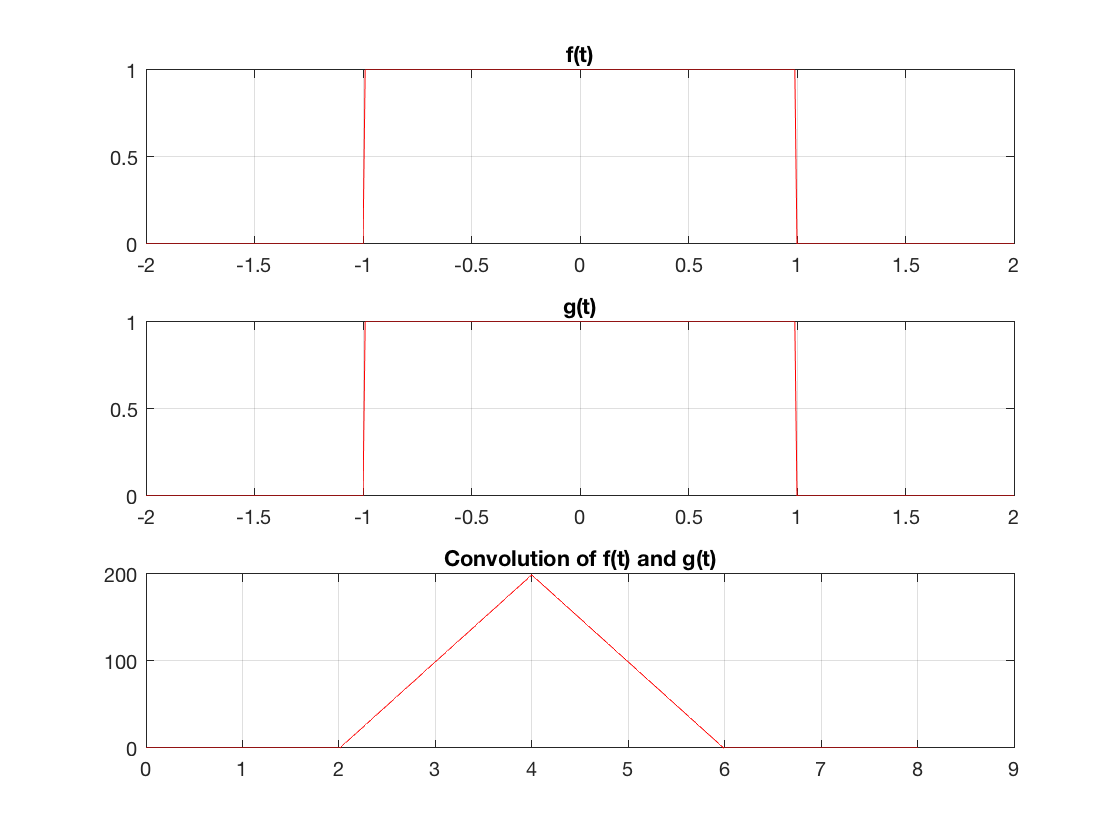

% (c)

close all
clearvars

A = 1;
a = 1;
t = -a*2:0.01:a*2;

f = A*(a>abs(t)); 

subplot(311); plot(t,f,'-r');hold on;
title('f(t)'); grid on; hold off;

g = A*(a>abs(t)); 

subplot(312); plot(t,f,'-r');hold on;
title('g(t)'); grid on; hold off;

% Convolution

y = conv(f,g,'full');
axis=(0:length(y)-1)*(t(2)-t(1));

subplot(313); plot(axis,y,'-r');hold on;
title('Convolution of f(t) and g(t)'); grid on; hold off;

# Problem 4

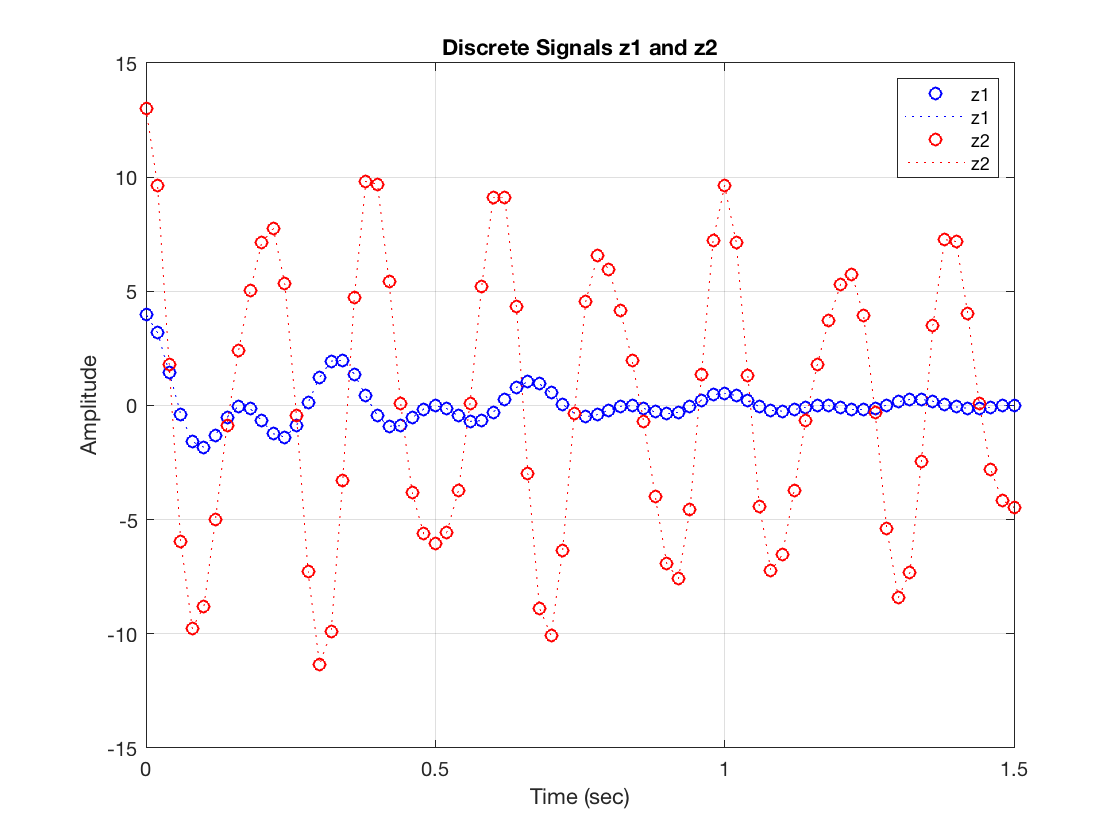

% (a)

clear; clc ; close all; 

a1 = 2;
b1 = 2;
c1 = 2;
f11 = 3;
f21 = 6;

a2 = 0.3;
b2 = 10;
c2 = 3;
f12 = 5;
f22 = 8;

ncycle = 5;
fs = 50;
t = 0:1/fs:ncycle;

z1 = exp(-a1*abs(t)).*(b1*cos(2*pi*f11*t)+c1*cos(2*pi*f21*t));

z2 = exp(-a2*abs(t)).*(b2*cos(2*pi*f12*t)+c2*cos(2*pi*f22*t));

plot(t,z1,'ob',t,z1,':b'); hold on;
plot(t,z2,'or', t, z2, ':r'); hold off;
grid on; xlim([0 1.5]);
ylabel('Amplitude'); 
xlabel('Time (sec)'); 
legend('z1','z1','z2','z2');
title('Discrete Signals z1 and z2');


% (b)

fz1 = fft(z1);
fz2 = fft(z2);

n = length(fz1);

P1 = abs(fz1/n);
p1 = P1(1:n/2+1);

p1(2:end-1) = 2*p1(2:end-1);

P2 = abs(fz2/n);
p2 = P2(1:n/2+1);

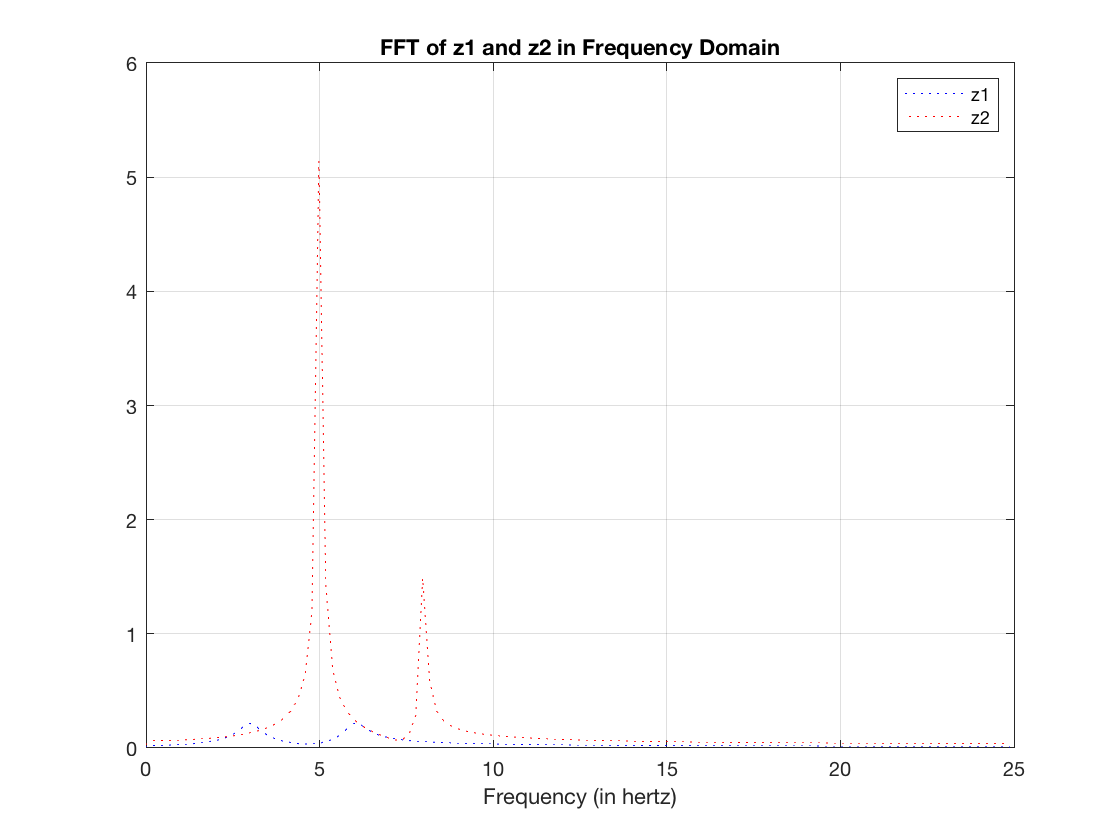

p2(2:end-1) = 2*p2(2:end-1);

f = fs*(0:(n/2))/n;


plot(f,p1,':b'); hold on;
plot(f,p2,':r'); hold off;
grid on;
xlabel('Frequency (in hertz)');
legend('z1','z2');
title('FFT of z1 and z2 in Frequency Domain');

# Problem 5

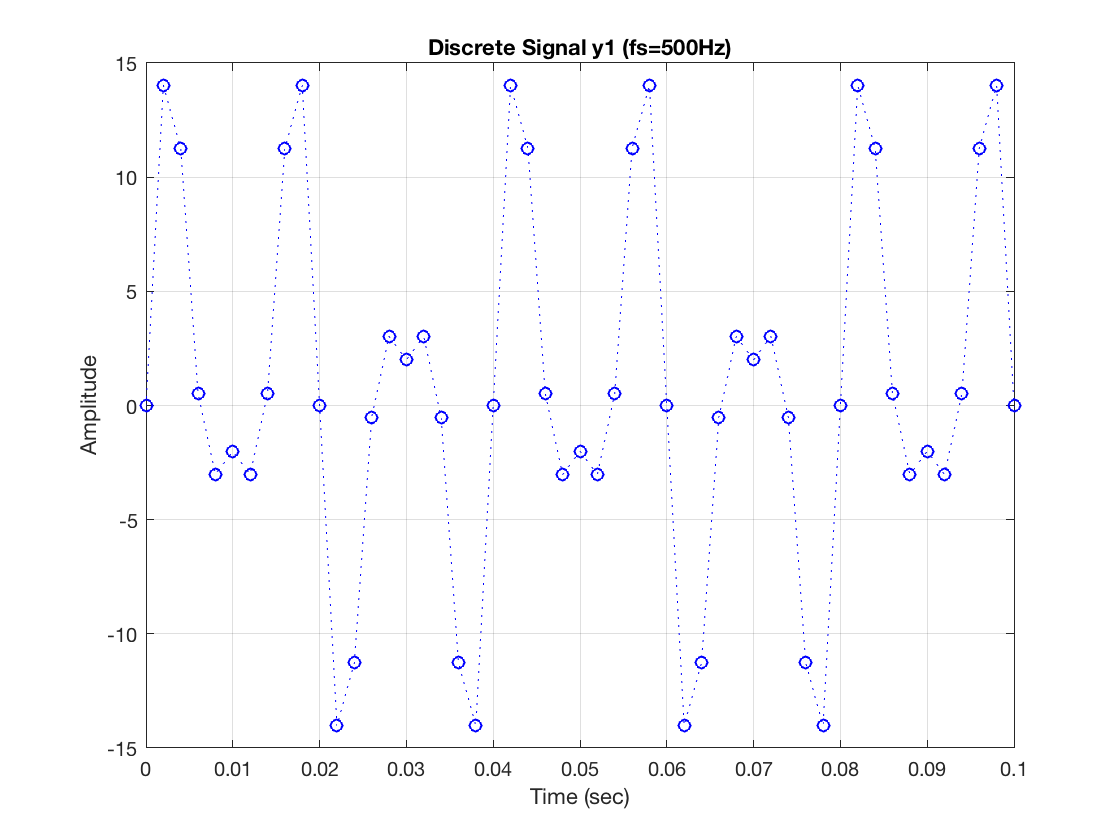

% (a)

clear; clc; close all; 

a1 = 3;
a2 = 10;
a3 = 5;

ncycle = 3;
fs = 500;
t = 0:1/fs:ncycle;

y1 = a1*sin(2*pi*(25)*t)+a2*sin(2*pi*(75)*t)+a3*sin(2*pi*(125)*t);

plot(t,y1,'ob',t,y1,':b'); 
grid on; xlim([0 0.1]);
ylabel('Amplitude'); 
xlabel('Time (sec)'); 
title('Discrete Signal y1 (fs=500Hz)');


% (b)

fy1 = fft(y1);

n = length(fy1);

P1 = abs(fy1/n);
p1 = P1(1:n/2+1);

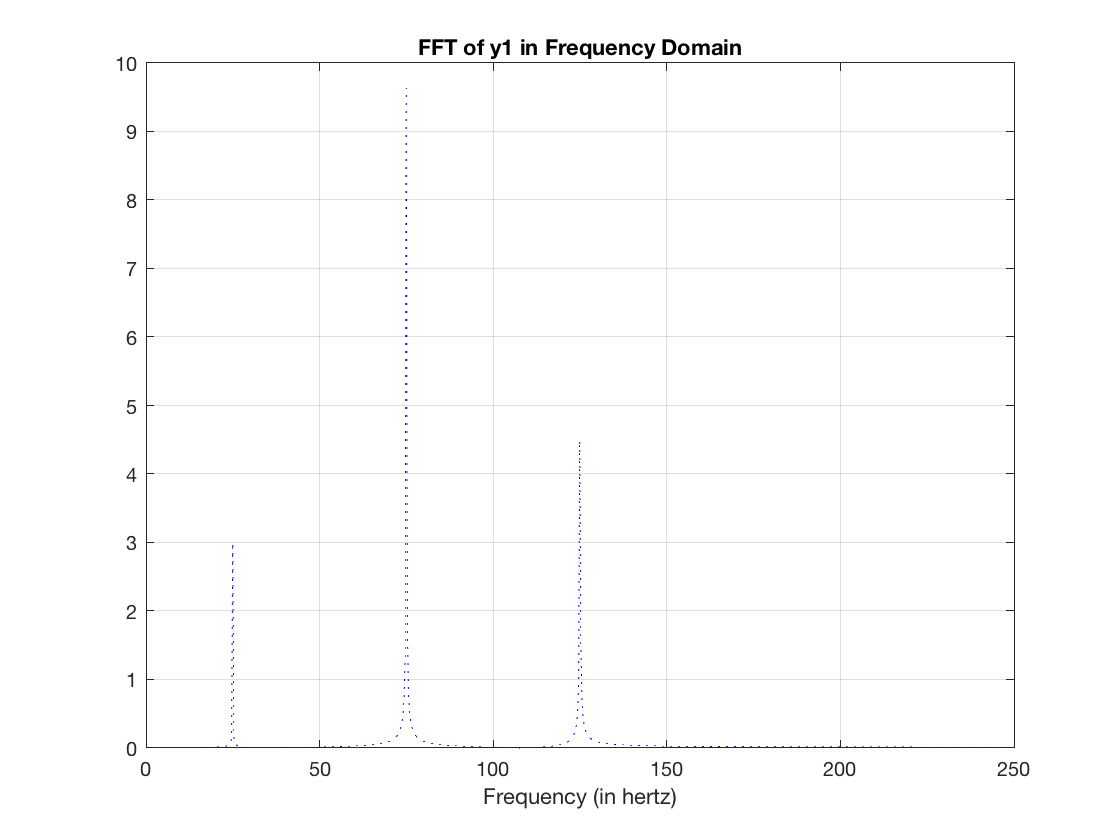

p1(2:end-1) = 2*p1(2:end-1);

f = fs*(0:(n/2))/n;

plot(f,p1,':b');
grid on;
xlabel('Frequency (in hertz)');
title('FFT of y1 in Frequency Domain');

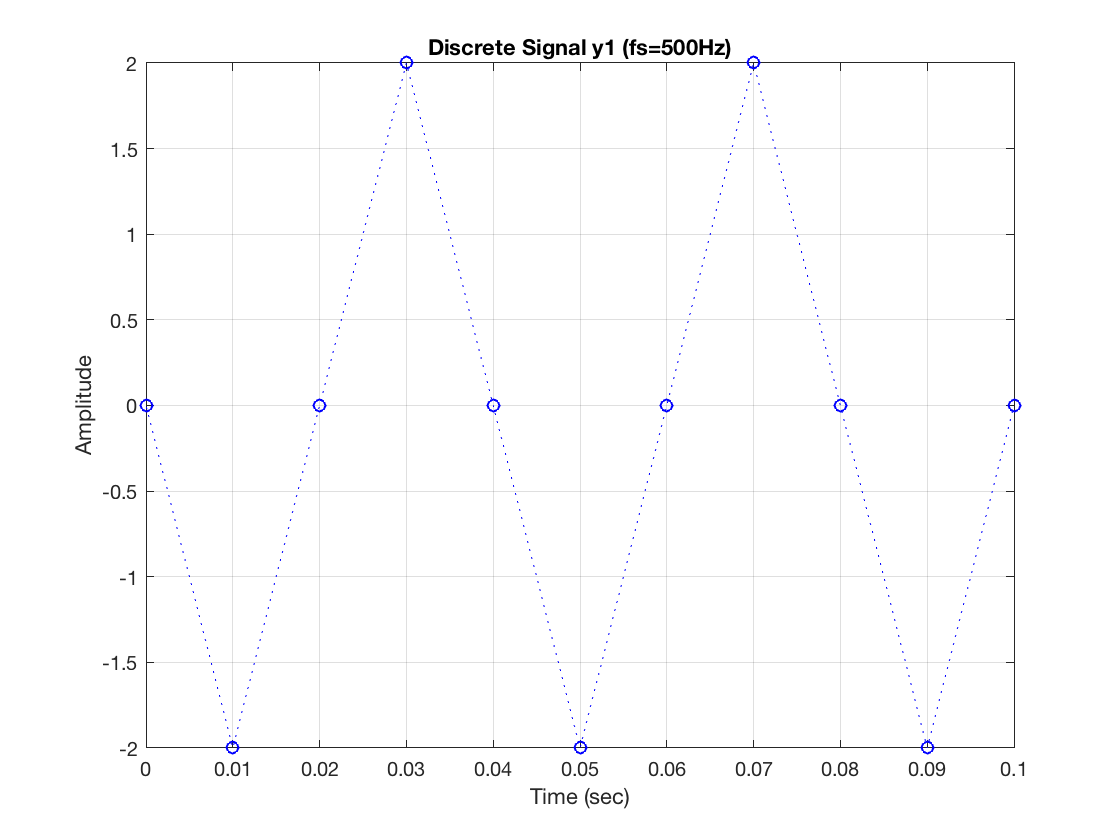


% (c)

clear; clc;

a1 = 3;
a2 = 10;
a3 = 5;

ncycle = 3;
fs = 100;
t = 0:1/fs:ncycle;

y1 = a1*sin(2*pi*(25)*t)+a2*sin(2*pi*(75)*t)+a3*sin(2*pi*(125)*t);

plot(t,y1,'ob',t,y1,':b'); 
grid on; xlim([0 0.1]);
ylabel('Amplitude'); 
xlabel('Time (sec)'); 
title('Discrete Signal y1 (fs=500Hz)');


% (d)

fy1 = fft(y1);

n = length(fy1);

P1 = abs(fy1/n);
p1 = P1(1:n/2+1);

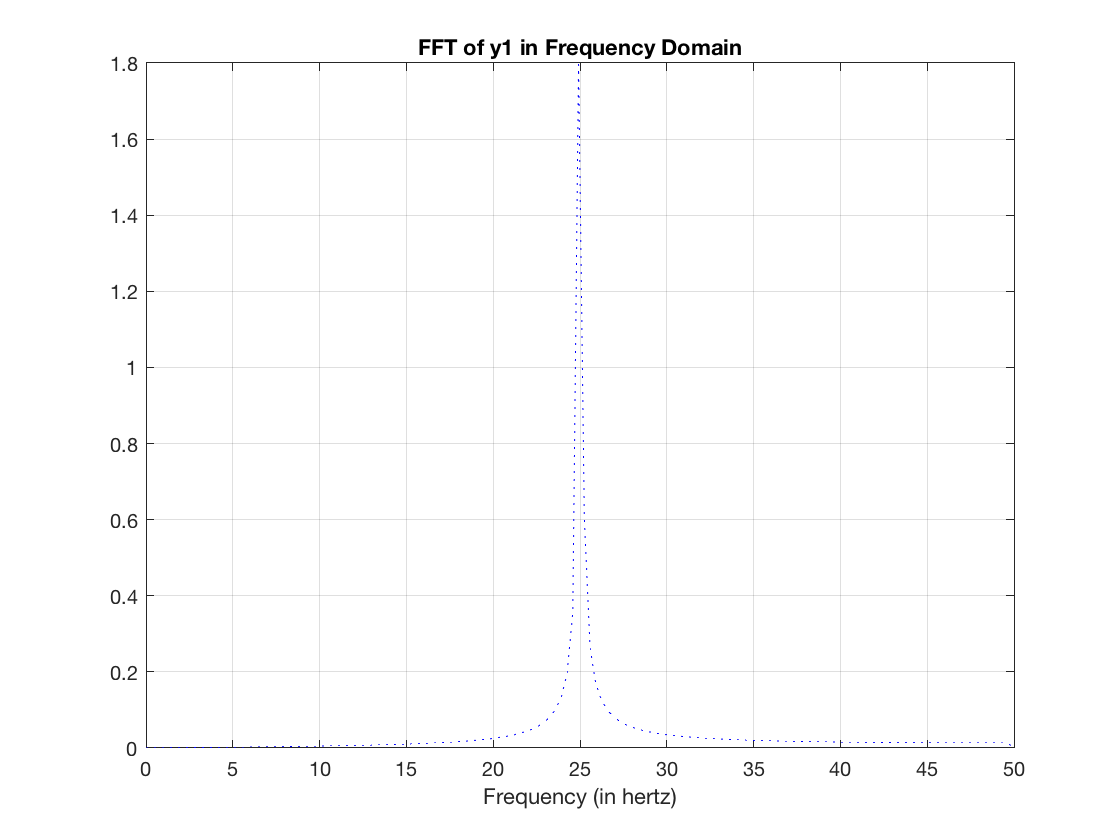

p1(2:end-1) = 2*p1(2:end-1);

f = fs*(0:(n/2))/n;

plot(f,p1,':b');
grid on;
xlabel('Frequency (in hertz)');
title('FFT of y1 in Frequency Domain');

# Problem 6

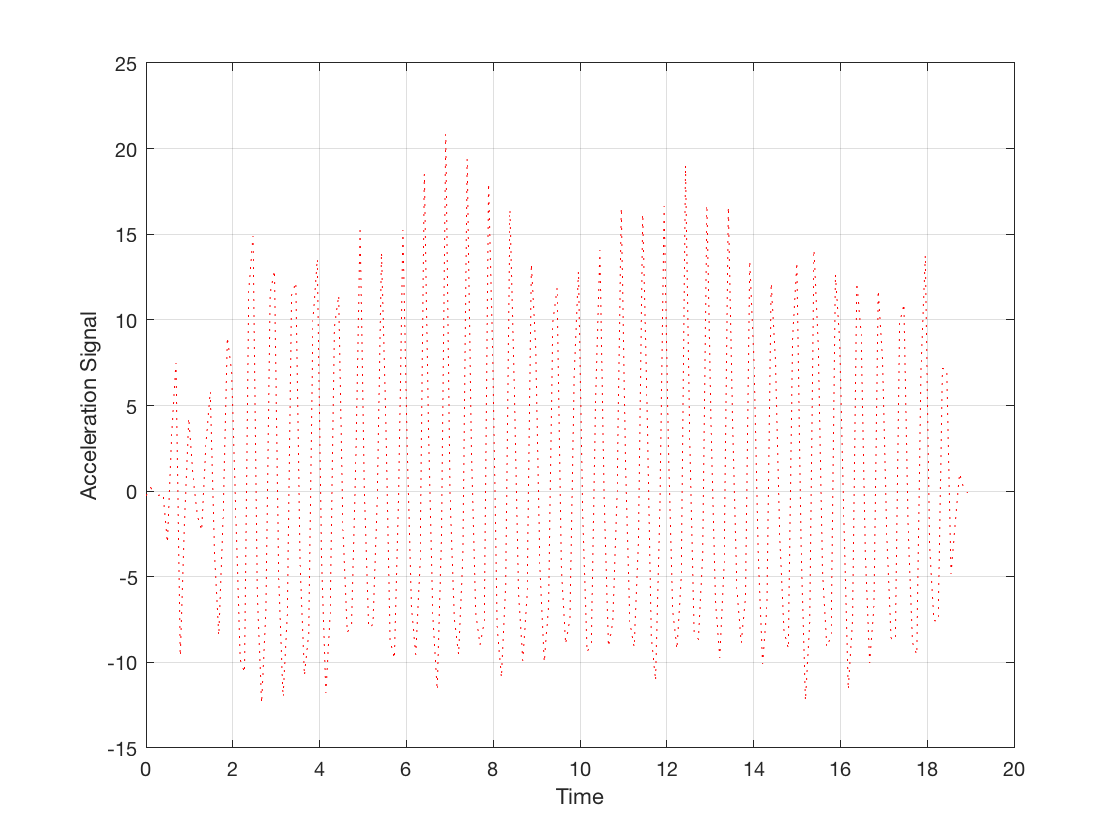

clear; clc; close all;

% (a)

load('vib_data1.mat');
plot(time,zvib,':r'); grid on;
xlabel('Time');
ylabel('Acceleration Signal');


fy1 = fft(zvib);

n = length(fy1);

P1 = abs(fy1/n);
p1 = P1(1:n/2+1);

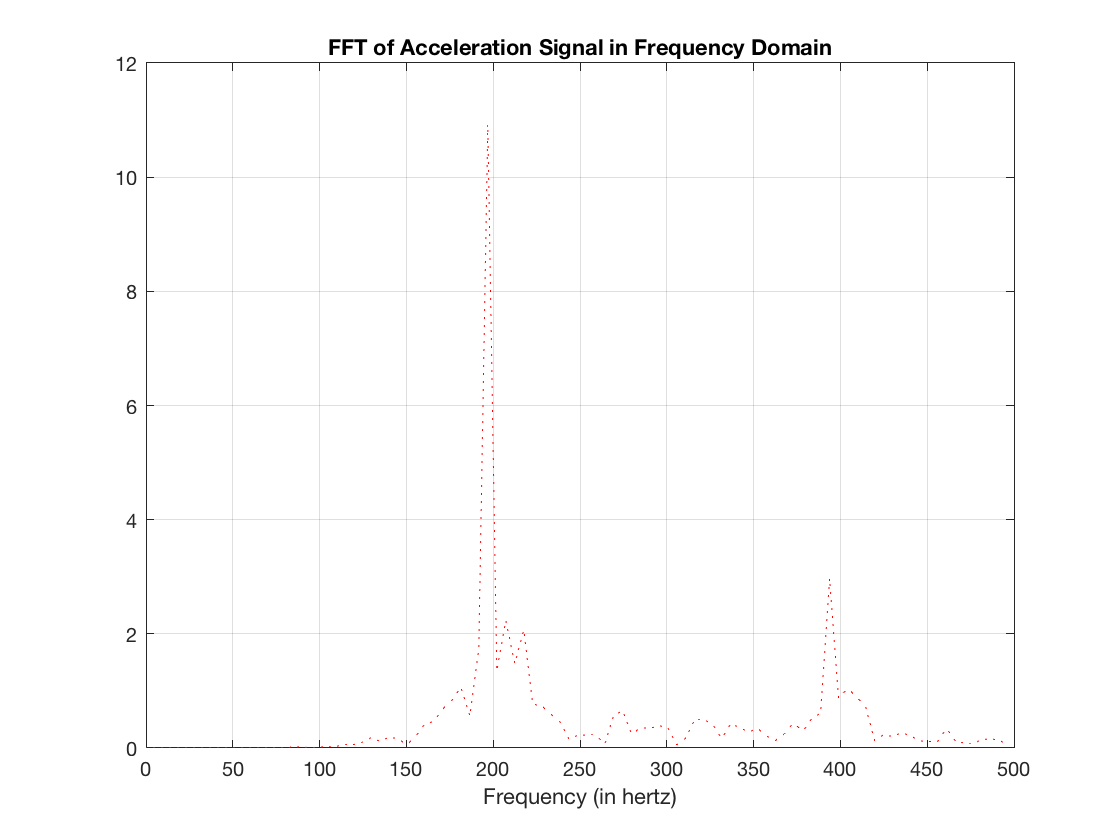

p1(2:end-1) = 2*p1(2:end-1);

f = 1000*(0:(n/2))/n;

plot(f,p1,':r');
grid on;
xlabel('Frequency (in hertz)');
title('FFT of Acceleration Signal in Frequency Domain');

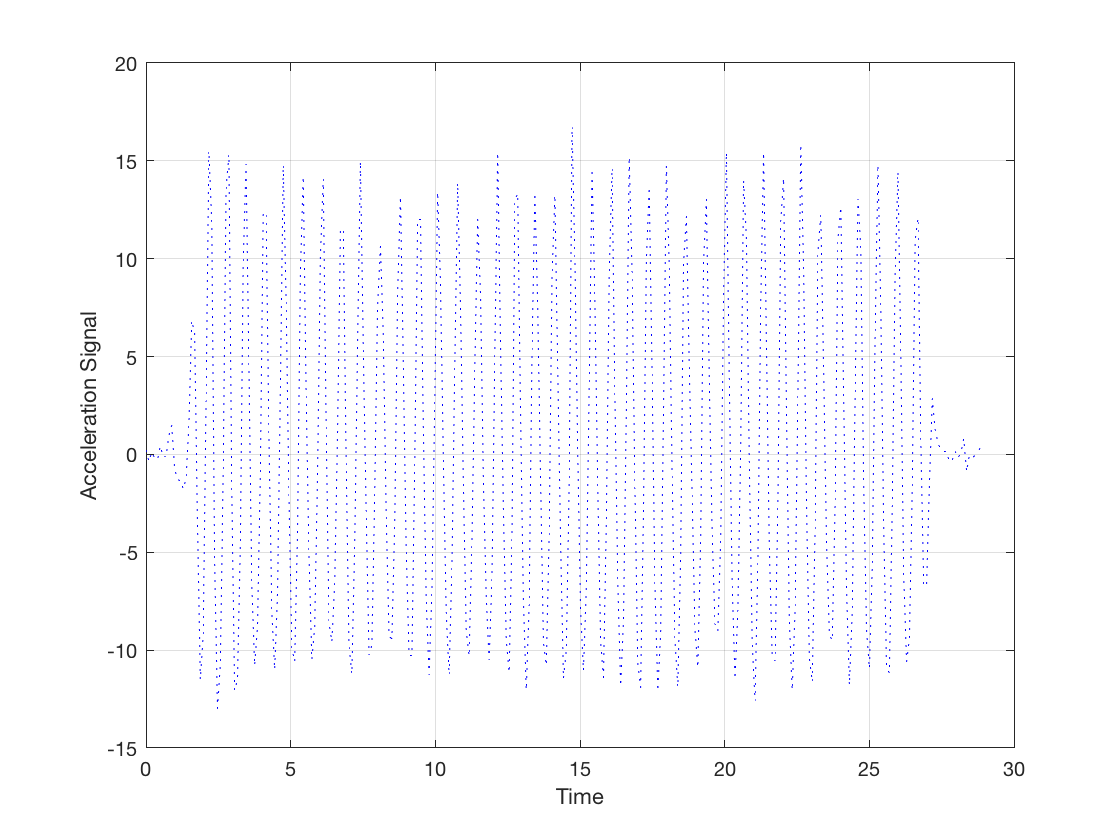


% The frequency of the wave is 200.

% (b)

clear; clc;

load('vib_data2.mat');
plot(time,zvib,':b'); grid on;
xlabel('Time');
ylabel('Acceleration Signal');


fy1 = fft(zvib);

n = length(fy1);

P1 = abs(fy1/n);
p1 = P1(1:n/2+1);

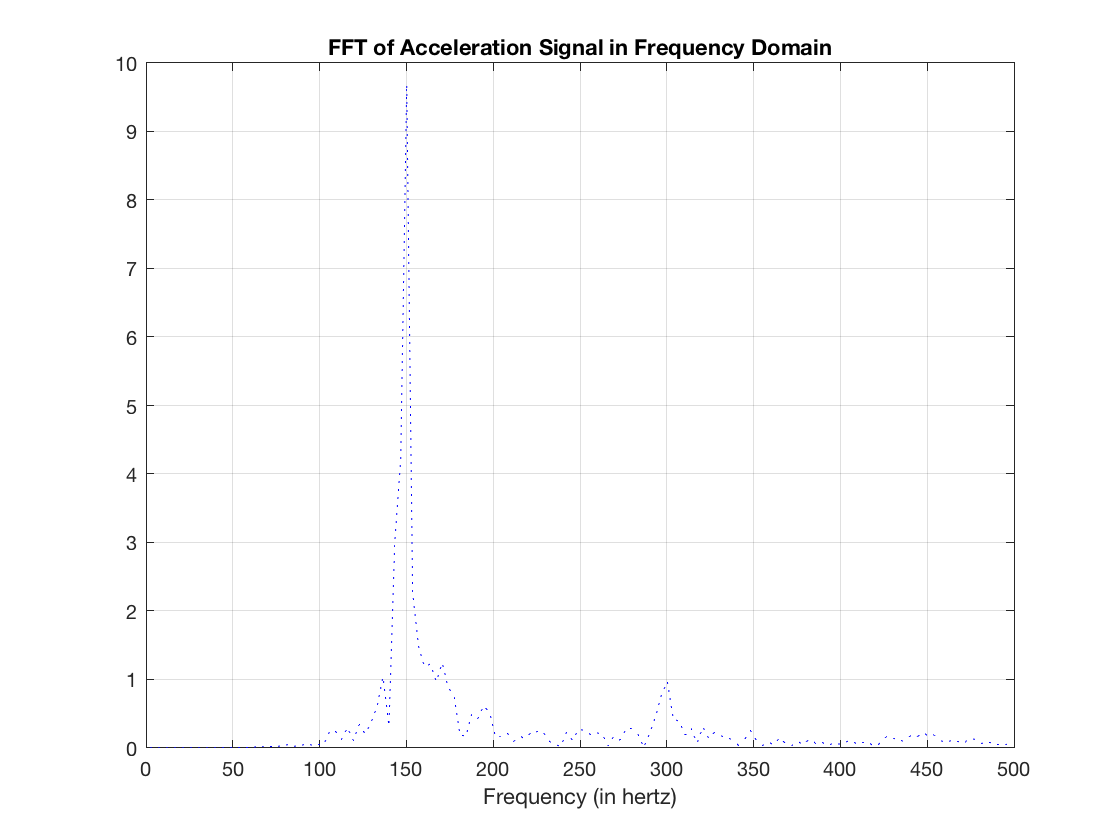

p1(2:end-1) = 2*p1(2:end-1);

f = 1000*(0:(n/2))/n;

plot(f,p1,':b');
grid on;
xlabel('Frequency (in hertz)');
title('FFT of Acceleration Signal in Frequency Domain');


% The frequency of the wave is 150.
